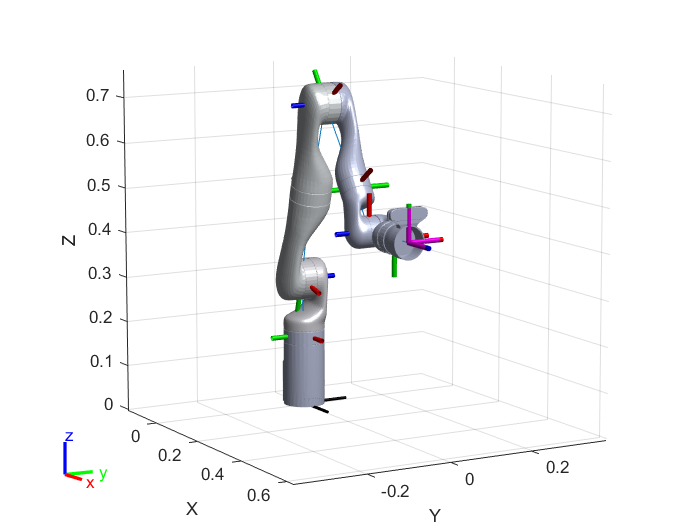

% To run this Matlab model install the following toolboxes
%  1)Robotics System Toolbox™
%  2)Simulink
%  3)Robotics System Toolbox™ Support Package for Manipulators
  
% Create Robot Model
gen3 = loadrobot("kinovaGen3");
gen3.DataFormat = 'column';
q_home = [0 15 180 -130 0 55 90]'*pi/180;
eeName = 'EndEffector_Link';
T_home = getTransform(gen3, q_home, eeName);
T_home(1:4,4) =  [0;0;0;1];

% Create Bounding Box
% bounding_box = rectangle('Position', [0.2 0.2 0.1 0.1], 'FaceColor', [0 0 1 0.5])

% Visualize the robot at home conifguration
show(gen3,q_home);
axis auto;
view([60,10]); 

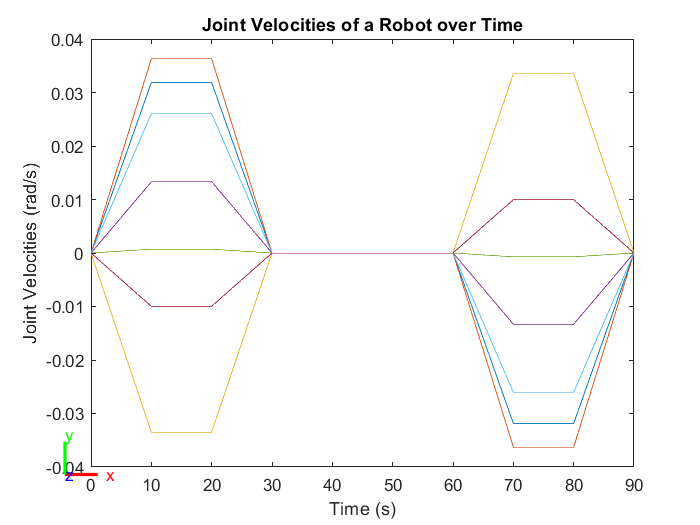


% Define a Set of Waypoints Based on the Tool Position
x = input('Enter x coordinate: ');
y = input('Enter y coordinate: ');
z = input('Enter z coordinate: ');
pitch = input('Enter pitch: ');
yaw = input('Enter yaw: ');
roll = input('Enter roll: ');

toolPositionHome = [0 0 0.75];
waypoints = toolPositionHome' + ... 
            [0 0 0 ; 0.2+x/2 y/2 z/2 ; 0.2+x/2 y/2 z/2 ; 0 0 0]';

% Define orientation
orientations = [pi/2 0 pi/2;
                pitch yaw roll;
                pitch yaw roll;
                pi/2 0 pi/2]';

% Define array of waypoint times
waypointTimes = 0:30:90;
% Trajectory Sample Time
ts = 0.25;
trajTimes = 0:ts:waypointTimes(end);

% Define boundary conditions for velocity and acceleration
waypointVels = [ 0.01  0.01  0.01;
                 0.01  0.01  0.01;
                 0  0  0;
                 0.01  0.01  0.01]';

waypointAccels = zeros(size(waypointVels));
waypointAccelTimes = diff(waypointTimes)/3;

% Create Inverse Kinematics Solver and Set Parameters
ik = inverseKinematics('RigidBodyTree',gen3);
ikWeights = [1 1 1 1 1 1];
ikInitGuess = q_home';
ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;



% Solve the Inverse Kinematics for Each Waypoint
includeOrientation = true; 
numWaypoints = size(waypoints,2);
numJoints = numel(gen3.homeConfiguration);
jointWaypoints = zeros(numJoints,numWaypoints);
for idx = 1:numWaypoints
    if includeOrientation
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform(orientations(:,idx)');
    else
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform([pi/2 0 pi/2]); %#ok<UNRCH> 
    end
    [config,info] = ik(eeName,tgtPose,ikWeights',ikInitGuess');
    jointWaypoints(:,idx) = config';
end

% Generate a Trajectory in Joint Space using Interpolation
trajType = 'trap';
switch trajType
    case 'trap'
        [q,qd,qdd] = trapveltraj(jointWaypoints,numel(trajTimes), ...
            'AccelTime',repmat(waypointAccelTimes,[numJoints 1]), ... 
            'EndTime',repmat(diff(waypointTimes),[numJoints 1]));
                            
    case 'cubic'
        [q,qd,qdd] = cubicpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'quintic'
        [q,qd,qdd] = quinticpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints), ...
            'AccelerationBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'bspline'
        ctrlpoints = jointWaypoints; % Can adapt this as needed
        [q,qd,qdd] = bsplinepolytraj(ctrlpoints,waypointTimes([1 end]),trajTimes);
        
    otherwise
        error('Invalid trajectory type! Use ''trap'', ''cubic'', ''quintic'', or ''bspline''');
end

% Plotting the angular velocity vs time
plot(trajTimes,qd);
xlabel('Time (s)');
ylabel('Joint Velocities (rad/s)');
title('Joint Velocities of a Robot over Time');

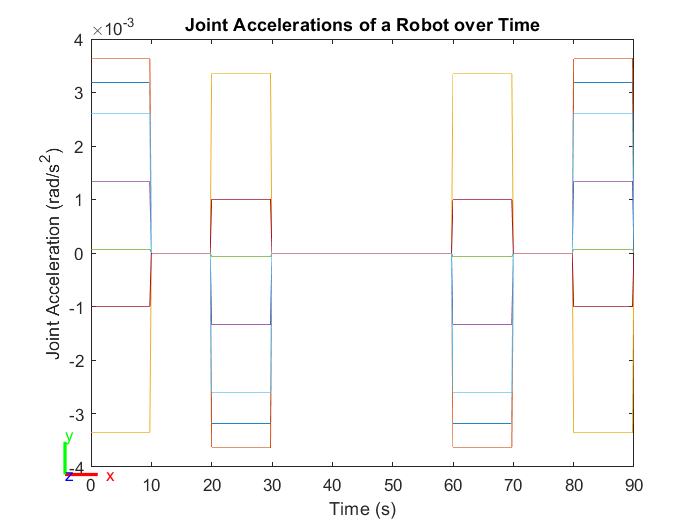


% Plotting the angular acceleration vs time
plot(trajTimes,qdd);
xlabel('Time (s)');
ylabel('Joint Acceleration (rad/s^2)');
title('Joint Accelerations of a Robot over Time');

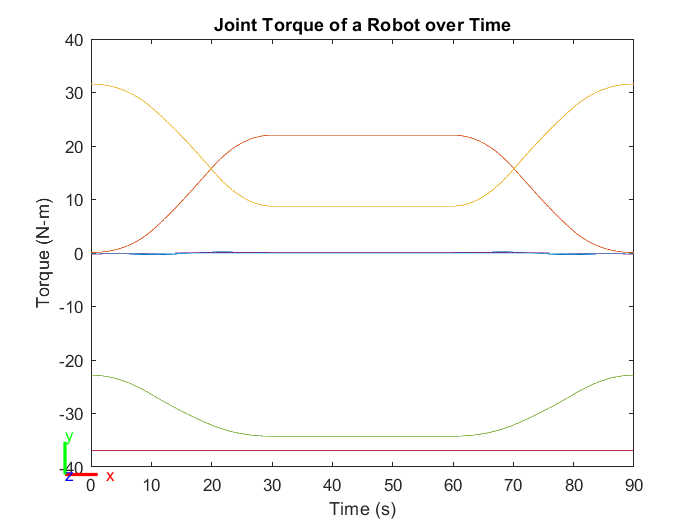


% Plotting the angular torque vs time
tmat = zeros(7,numel(trajTimes));

wrench = [0 0 -66.395 0 0 0];

for b = 1:numel(trajTimes)
  jointTorq = inverseDynamics(gen3,q(:,b),qd(:,b),qdd(:,b),externalForce(gen3, 'EndEffector_Link',wrench,q(:,b)));
  tmat(:,b) = jointTorq;
end

plot(trajTimes,tmat);
xlabel('Time (s)');
ylabel('Torque (N-m)');
title('Joint Torque of a Robot over Time');


% Plotting the Power vs Time
pavg = 0;
for c = 1:7
  for do = 1:numel(trajTimes)
    pmat(c,do) = tmat(c,do)*qd(c,do);
    if pmat(c,do) < 0
        pmat(c,do) = -pmat(c,do);
    end
    pavg = pavg + pmat(c,do);
  end
end
pavg = pavg/numel(trajTimes);
disp("Average power over a cycle is: ");

Average power over a cycle is: 


disp(pavg);

    0.6539



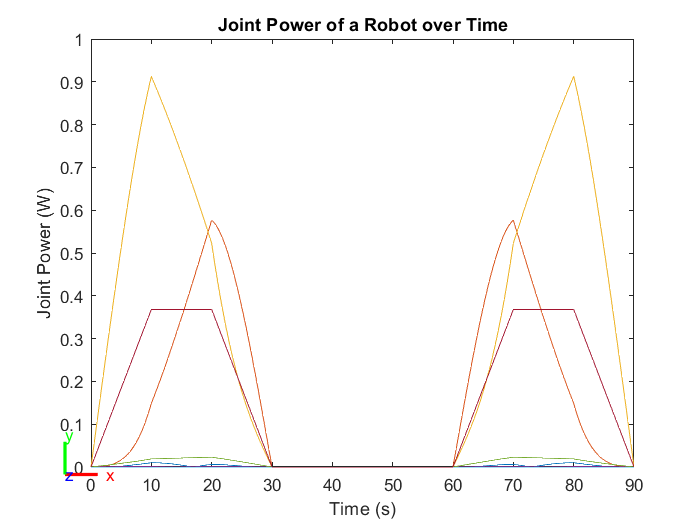


plot(trajTimes,pmat);
xlabel('Time (s)');
ylabel('Joint Power (W)');
title('Joint Power of a Robot over Time');


% Set Plot and Display Waypoints
plotMode = 1; % 0 = None, 1 = Trajectory, 2 = Coordinate Frames
show(gen3,q_home,'Frames','off','PreservePlot',false);
hold on
if plotMode == 1
    hTraj = plot3(waypoints(1,1),waypoints(2,1),waypoints(3,1),'b.-');
end
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);
axis auto;
view([30 15]);

% Visualize the Solution
for idx = 1:numel(trajTimes)  
 
    config = q(:,idx)';

    % Find Cartesian points for visualization
    eeTform = getTransform(gen3,config',eeName);
    if plotMode == 1
        eePos = tform2trvec(eeTform);
        set(hTraj,'xdata',[hTraj.XData eePos(1)], ...
                  'ydata',[hTraj.YData eePos(2)], ...
                  'zdata',[hTraj.ZData eePos(3)]);
    elseif plotMode == 2
        plotTransforms(tform2trvec(eeTform),tform2quat(eeTform),'FrameSize',0.05);
    end
 
    % Show the robot
    show(gen3,config','Frames','off','PreservePlot',false);
    title(['Trajectory at t = ' num2str(trajTimes(idx))])
    drawnow   
    
end

Invalid or deleted object.